% Simulation parametri
casovniKorak = 0.01;
% Parametri simulacije
Ts = 0.01;  % Vzorec (Sample time)
N_sim = 10000;  % Število simulacijskih korakov
H = 3;  % Število upoštevanih členov

% Naloži Takagi-Sugeno model
model = load('model_luka.mat');  % Nalaganje modela iz datoteke
C = model.C;
O = model.O;
W = model.W;
b = model.b;
%

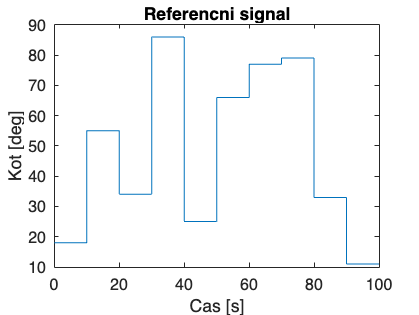


% Referenčni sistem (1. reda)
s = tf('s');
G_ref = 5 / (s + 5);  % Prenosna funkcija referenčnega sistema
sys_ref = c2d(ss(G_ref), Ts, 'zoh');  % Diskretizacija referenčnega sistema
%[A_ref, B_ref, C_ref, ~] = ssdata(sys_ref);
A_ref = sys_ref.A;
B_ref = sys_ref.B;
C_ref = sys_ref.C;


% Ustvarjanje referenčnega signala
cas = 0:casovniKorak:99.99;
steviloTock = length(cas);
referencniSignal = zeros(1, steviloTock);
amplitude = [18, 55, 34, 86, 25, 66, 77, 79, 33, 11];
casovniInterval = steviloTock / length(amplitude);

for i = 1:length(amplitude)
    zacetek = (i - 1) * casovniInterval + 1;
    konec = i * casovniInterval;
    referencniSignal(zacetek:konec) = amplitude(i);
end
figure;
plot(cas, referencniSignal);
title("Referencni signal");
xlabel("Cas [s]");
ylabel("Kot [deg]");

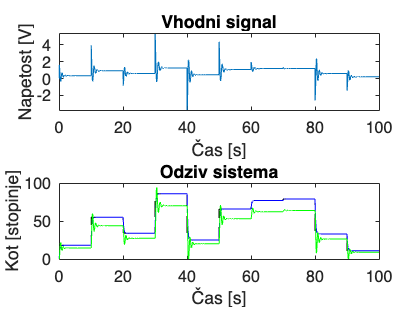


% Inicializacija stanj in vhodnih signalov
x_ref = 0;
x_model = [0; 0];
x_process = [0; 0];
u = zeros(1, N_sim);
y_model = zeros(1, N_sim);          % model
y_process = zeros(1, N_sim);        % proces
y_ref = zeros(1, N_sim);            % referencni signal

% Koeficienti za funkcijski regulator
for k = 3:N_sim
    % Izračun napake
    y_ref(k) = C_ref * x_ref;  % Izhod referenčnega sistema
    e = referencniSignal(k) - y_process(k-1);  % Napaka glede na proces, na zaćetku je y_process = 0

    % Izračunovanje matrik sistema na podlagi TS modela za trenutno stanje modela
    [A_m, B_m, C_m, R_m] = Convert(C, O, W, b, [-y_process(k-1); -y_process(k-2)]);

    % Prediktivni regulator
    G0 = C_m * (A_m^H - eye(size(A_m))) * pinv(A_m - eye(size(A_m))) * B_m;
    G = pinv(G0) * (1 - A_ref^H);

   
    % Posodobitev stanj za referenčni, modelni in procesni sistem
    x_ref = A_ref * x_ref + B_ref * referencniSignal(k);
    x_model = A_m * x_model + B_m * u(k) + R_m;
    y_model(k) = C_m * x_model;

     % Krmilni signal
    u(k) = G * e + pinv(G0) * y_model(k-1) - pinv(G0) * C_m * (A_m^H) * x_model - pinv(B_m) * R_m;


    % Procesni model (Helicrane)
    [x_process(2), x_process(1)] = helicrane(u(k), x_process);
    y_process(k) = x_process(2);
end

% Prikaz rezultatov
figure;
subplot(2, 1, 1);
plot(cas, u);
title('Vhodni signal');
xlabel('Čas [s]');
ylabel('Napetost [V]');

subplot(2, 1, 2);
plot(cas, referencniSignal, 'k--');
hold on;
plot(cas, y_ref, 'b');
plot(cas, y_process, 'g');
%legend('Referenčni signal', 'Modelni izhod', 'Izhod procesa');
title('Odziv sistema');
xlabel('Čas [s]');
ylabel('Kot [stopinje]');


function [A_state, B_state, C_state, R_state] = Convert(centers, spreads, weights, offsets, input)
    % Convert Takagi-Sugeno model to state-space model

    numRules = size(centers, 1);  % Number of rules
    [A_state, B_state, C_state, R_state] = deal(zeros(2, 2), zeros(2, 1), zeros(1, 2), zeros(2, 1));

    membershipValues = exp(-0.5 * sum((input' - centers).^2 ./ (spreads.^2), 2));  % Gaussian function - 16x1
    membershipValues = membershipValues / sum(membershipValues);  % Normalization

    % Construct state matrices with weighting
    for ruleIndex = 1:numRules
        A_rule = [0, -weights(ruleIndex, 4); 1, -weights(ruleIndex, 3)];
        B_rule = [weights(ruleIndex, 2); weights(ruleIndex, 1)];
        C_rule = [0, 1];
        R_rule = [0; offsets(ruleIndex)];

        A_state = A_state + membershipValues(ruleIndex) * A_rule;
        B_state = B_state + membershipValues(ruleIndex) * B_rule;
        C_state = C_state + membershipValues(ruleIndex) * C_rule;
        R_state = R_state + membershipValues(ruleIndex) * R_rule;
    end
    input=0;
    
end
